## Read the data

data = readtable("data/word_analysis.csv")

data = 129971×14 table
    Var1      country                                                                                                                                                             description                                                                                                                                                                        designation                  points    price          province                  region_1                  region_2                taster_name          taster_twitter_handle                                             title                                                    variety                    winery         
    ____    ____________    

## Get all words

try
    load("data/all_words.mat")
catch
    num_reviews = size(data,1);
    all_words = cell(num_reviews,1);
    punctuation = {'.',',','!'};
    
    for i = 1:num_reviews
        % get review
        review = data.('description'){i};
        
        % remove punctuation
        for k = 1: size(punctuation,2)
            review = strrep(review, punctuation{k}, "");
        end
        
        % save to cell array
        all_words(i) = {lower(split(review, " "))};
    end
end

## Filter

e.g. by price category of type of wine

% TODO

## Get word counts

This combines all of the reviews

try
    load("data/word_counts.mat")
catch
    answer = questdlg(['Do you want to count the words? ' ...
        'This will take a long time.']);
    if strcmp(answer, 'Yes')
        disp('Be patient!')
    else
        return
    end
    
    word_counts = struct('word', {"the"}, 'count', {0})
    
    for i = 1:numel(all_words)
        
        review = all_words{i};
        
        for k = 1:numel(review)
           
            word = review(k);
            idx = find(word_counts.word==word);
            if ~isempty(idx)
                word_counts.count(idx) = word_counts.count(idx) + 1;
            else
                word_counts.word{end+1} = char(word);
                word_counts.count(end+1) = 1;
            end
        end
    end
    
    % Sort word counts
    [counts_sorted, I] = sort(word_counts.count, 'descend');
    words_sorted = word_counts.word(I);
    
    % Save sorted word counts
    word_counts.word = words_sorted;
    word_counts.count = counts_sorted;
end

## Combine by Relatedness

Uses ConceptNet to combine words, depending on their relatedness

#### Import Python Function

pyenv('Version', '/Users/kevinhuestis/anaconda3/bin/python');
module = py.importlib.import_module('combine_by_relatedness');

#### Run

words = cellstr(word_counts.word);
counts = word_counts.count;

relations = module.get_relations(words(1:50), counts(1:50));

## Analysis

### Convert to Table

num_top_words = 150;
num_total_words = sum(word_counts.count);
num_reviews = size(all_words,1);
    
try
    load("data/review_stats.mat")
    Word = word_counts.word(1:num_top_words);
    Count = word_counts.count(1:num_top_words);
    Percent = round(100 * Count / num_total_words, 3);
    Num_Reviews = str2double(top_words.Num_Reviews);
    Percent_Reviews = str2double(top_words.Percent_Reviews);
catch
    Word = word_counts.word(1:num_top_words);
    Count = word_counts.count(1:num_top_words);
    Percent = round(100 * Count / num_total_words, 3);
    Num_Reviews = get_num_reviews(Word, all_words);
    Percent_Reviews = round(100 * Num_Reviews / num_reviews, 3);
    top_words = array2table([Word; Count; Percent; Num_Reviews; Percent_Reviews]');
    top_words.Properties.VariableNames = {'Word', 'Count', 'Percent', 'Num_Reviews', 'Percent_Reviews'};
end

top_words

top_words = 150×5 table
      Word        Count      Percent    Num_Reviews    Percent_Reviews
    _________    ________    _______    ___________    _______________

    "and"        "347334"    "6.617"     "127233"         "97.893"    
    "the"        "220803"    "4.207"     "104894"         "80.706"    
    "a"          "179321"    "3.416"     "102646"         "78.976"    
    "of"         "172911"    "3.294"     "99529"          "76.578"    
    "with"       "120243"    "2.291"     "85310"          "65.638"    
    "this"       "113979"    "2.172"     "98399"          "75.708"    
    "is"         "96698"     "1.842"     "70080"          "53.92"     
    "wine"       "77859"     "1.483"     "62912"          "48.405"    
    "flavors"    "62608"     "1.193"     "59476"          "45.761"    
    "in"         "62243"

#### Plots

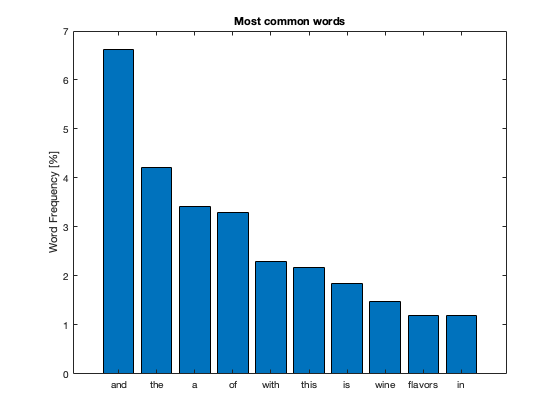

bar(Percent(1:10));
% fig1.Parent.OuterPosition = [0 0 1.5 1];
title("Most common words")
ylabel("Word Frequency [%]")
set(gca,'xticklabel',Word(1:10))

#### Filter Useless Words

useless = ["and"; "the"; "a"; "of"; "with"; "this"; "is"; "in"; "it"; "to"; ...
    "on"; "that"; "from"; "but"; "it's"; "are"; "has"; "for"; "by"; "as"; "an"; "its"];

% Filter useless words
filt = any(Word == useless);
Percent(filt) = [];
Word(filt) = [];

#### Plots

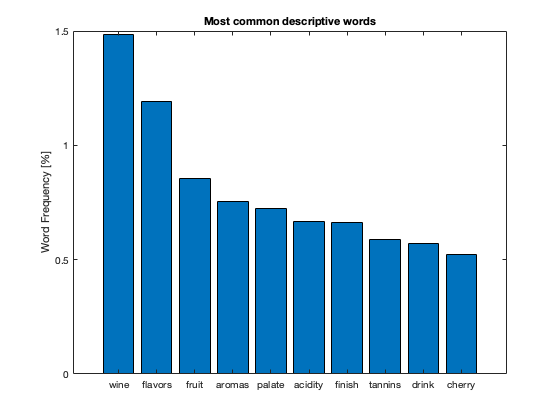

bar(Percent(1:10));
title("Most common descriptive words")
ylabel("Word Frequency [%]")
set(gca,'xticklabel',Word(1:10))

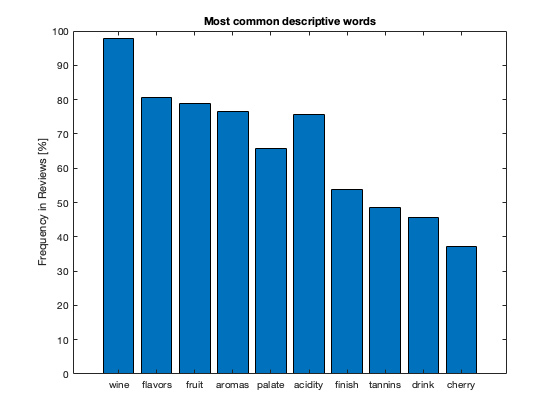


bar(Percent_Reviews(1:10));
title("Most common descriptive words")
ylabel("Frequency in Reviews [%]")
set(gca,'xticklabel',Word(1:10))